x = 1:1:50;
r = 10;
p = 0.35;

% Y = nbinpdf(x, r, p);
% plot(x, Y);











time = 22;
beta_n = 4e-9;              % DP to R and I, IP to S
epsilon_n = 1e-10;          % DP to I
gamma_n = 0.2e-1;%0.0396;     % DP to R, IP to I
% lambda_n = NA;

beta_p = 1.8e-10;
epsilon_p = 1.5e-10;
gamma_p = 0.8e-1;
% lambda_p = NA;
delta = 0;
par = [beta_n, epsilon_n gamma_n beta_p epsilon_p gamma_p delta];
inital_values = [19005317 1090 1037 10318 110 91];

model_out = SIRS_free(par, inital_values, time);

Unrecognized function or variable 'SIRS_free'.


close all;
subplot(3,1,1)
hold on
plot(t, data(1,:), 'k.')
plot(t, model_out(1,:))
xlabel('Years'), ylabel('S-')
title('S-')
hold off;

subplot(3,1,2)
hold on;
plot(t, data(2,:), 'k.')
plot(t, model_out(2,:))
xlabel('Years'), ylabel('I-')
title('I-')
hold off


subplot(3,1,3)
hold on;
plot(t, data(3,:), 'k.')
plot(t, model_out(3,:))
xlabel('Years'), ylabel('R-')
title('R-')
hold off










time = 22;
beta_n = 4e-9;              % DP to R and I, IP to S
epsilon_n = 1e-35;          % DP to I
gamma_n = 0.2e-1;%0.0396;     % DP to R, IP to I
% lambda_n = NA;

beta_p = 3e-15;             % DP to , IP to
epsilon_p = 4.5e-1;           % DP to S, IP to R
gamma_p = 5.5e-1;             % DP to , IP to I
% lambda_p = NA;
delta = 0;
par = [beta_n, epsilon_n gamma_n beta_p epsilon_p gamma_p delta];
inital_values = [19005317 1090 1037 10318 110 91];

model_out = SIRS_free(par, inital_values, time);

close all;
subplot(3,1,1)
hold on
plot(t, data(4,:), 'k.')
plot(t, model_out(4,:))
xlabel('Years'), ylabel('S+')
title('S+')
hold off;

subplot(3,1,2)
hold on;
plot(t, data(5,:), 'k.')
plot(t, model_out(5,:))
xlabel('Years'), ylabel('I+')
title('I+')
hold off


subplot(3,1,3)
hold on;
plot(t, data(6,:), 'k.')
plot(t, model_out(6,:))
xlabel('Years'), ylabel('R+')
title('R+')
hold off



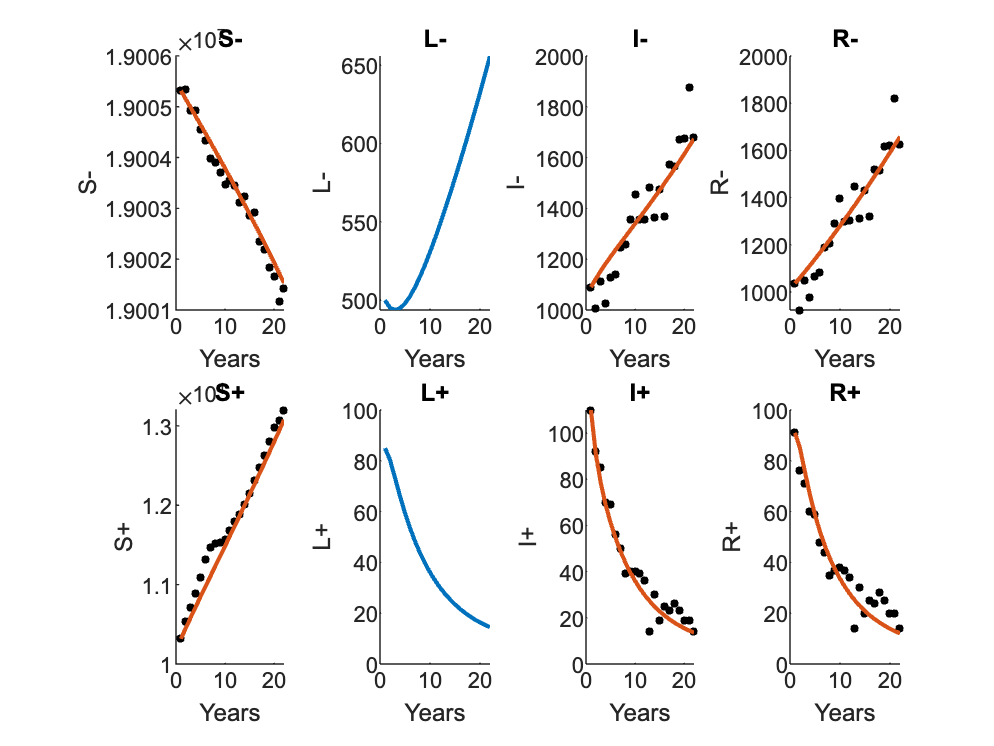

% 
% time = 22;
% beta_n = 2.5e-9;              % DP to R and I, IP to S
% epsilon_n = 2e-5;          % DP to I, IP to R
% gamma_n = 0.25e-1;%0.0396;     % DP to R, IP to I
% % lambda_n = NA;
% 
% beta_p = 4e-5;             % DP to , IP to
% epsilon_p = 7e-1;           % DP to S, IP to R
% gamma_p = 5.5e-1;             % DP to , IP to I
% % lambda_p = NA;
% delta =  10^(-5.16);%6.5e-6;
% par = [beta_n, epsilon_n gamma_n beta_p epsilon_p gamma_p delta];
% inital_values = [19005317 1090 1037 10318 110 91];


time = 22;
beta_n = 4.5e-9;              % DP to R and I, IP to S
epsilon_n = 4e-2;          % DP to I, IP to R
gamma_n = 6e-2;%0.0396;     % DP to R, IP to I
lambda_n =  2e-1;

beta_p = 4e-5;             % DP to , IP to
epsilon_p = 8e-1;           % DP to S, IP to R
gamma_p = 6.5e-1;             % DP to , IP to I
lambda_p = 5.5e-1;
delta = 5.5e-10;


L_n_0 = 0.5e3;
L_p_0 = 8.5e1;  


par = [beta_n, epsilon_n gamma_n beta_p epsilon_p gamma_p delta 0 lambda_n lambda_p];
inital_values = [19005317 1090 1037 10318 110 91 L_n_0 L_p_0];



model_out = SLIR_free(par, inital_values, time);

close all;
subplot(2,4,1)
hold on
plot(t, data(1,:), 'k.')
plot(t, model_out(1,:)+model_out(7,:))

xlabel('Years'), ylabel('S-')
title('S-')
hold off;

subplot(2,4,2)
hold on;
% plot(t, data(2,:), 'k.')
plot(t, model_out(7,:))
xlabel('Years'), ylabel('L-')
title('L-')
hold off

subplot(2,4,3)
hold on;
plot(t, data(2,:), 'k.')
plot(t, model_out(2,:))
xlabel('Years'), ylabel('I-')
title('I-')
hold off

subplot(2,4,4)
hold on
plot(t, data(3,:), 'k.')
plot(t, model_out(3,:))
xlabel('Years'), ylabel('R-')
title('R-')
hold off;

subplot(2,4,5)
hold on;
plot(t, data(4,:), 'k.')
plot(t, model_out(4,:)+model_out(8,:))
xlabel('Years'), ylabel('S+')
title('S+')
hold off


subplot(2,4,6)
hold on;
% plot(t, data(6,:), 'k.')
plot(t, model_out(8,:))
xlabel('Years'), ylabel('L+')
title('L+')
hold off

subplot(2,4,7)
hold on;
plot(t, data(5,:), 'k.')
plot(t, model_out(5,:))
xlabel('Years'), ylabel('I+')
title('I+')
hold off


subplot(2,4,8)
hold on;
plot(t, data(6,:), 'k.')
plot(t, model_out(6,:))
xlabel('Years'), ylabel('R+')
title('R+')
hold off

% % % % % % % % % % % % 3x3 Plot

time = 22;
beta_n = 4.5e-11;              % DP to R and I, IP to S
epsilon_n = 2e-5;          % DP to I, IP to R
gamma_n = 0.25e-1;%0.0396;     % DP to R, IP to I
lambda_n = 0e-5;

beta_p = 4e-5;             % DP to , IP to
epsilon_p = 7e-1;           % DP to S, IP to R
gamma_p = 5.5e-1;             % DP to , IP to I
lambda_p = 0e-5;
delta =  (-5.16);%6.5e-6;


L_n_0 = 0;
L_p_0 = 0;


par = [beta_n, epsilon_n gamma_n beta_p epsilon_p gamma_p delta 0 lambda_n lambda_p];
inital_values = [19005317 0 1090 1037 10318 110 91 L_n_0 L_p_0];



model_out = SLIR(par, inital_values, time);

close all;
subplot(2,3,1)
hold on
plot(t, data(1,:), 'k.')
plot(t, model_out(1,:)+model_out(7,:))

xlabel('Years'), ylabel('S-')
title('S-')
hold off;


subplot(2,3,2)
hold on;
plot(t, data(2,:), 'k.')
plot(t, model_out(3,:))
xlabel('Years'), ylabel('I-')
title('I-')
hold off

subplot(2,3,3)
hold on
plot(t, data(3,:), 'k.')
plot(t, model_out(4,:))
xlabel('Years'), ylabel('R-')
title('R-')
hold off;

subplot(2,3,4)
hold on;
plot(t, data(4,:), 'k.')
plot(t, model_out(5,:)+model_out(8,:))
xlabel('Years'), ylabel('S+')
title('S+')
hold off


subplot(2,3,5)
hold on;
plot(t, data(5,:), 'k.')
plot(t, model_out(7,:))
xlabel('Years'), ylabel('I+')
title('I+')
hold off


subplot(2,3,6)
hold on;
plot(t, data(6,:), 'k.')
plot(t, model_out(8,:))
xlabel('Years'), ylabel('R+')
title('R+')
hold off



